detectBout();

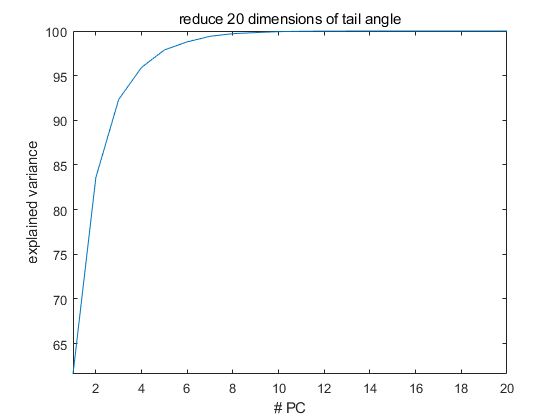

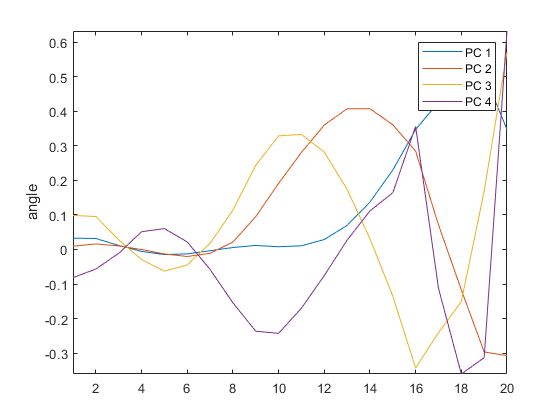

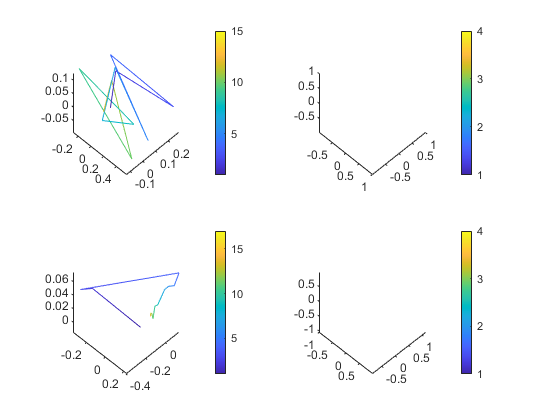

postfix = '_curv';
reduceTailDim(postfix);

dtw_alignBout(postfix);

Affinity Propagation Clustering...
next hierarchical clustering....


evaluating the clustering result


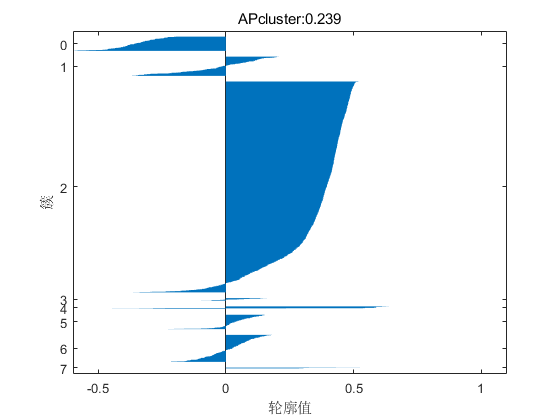

[idx_apcluster,exemplar,sz_cluster] = embedBout2Cluster(1,postfix);

find the exemplar of each cluster, or is the bout really similar to each other under one cluster

[sessionID,fishID] = getfish();
numBout_per_fish = zeros(length(sessionID),1);
for i=1:length(sessionID)
   load(fullfile(getpath('behavior',sessionID{i},fishID{i}),'tail_swing'),'bout_idx') ;
   numBout_per_fish(i) = length(bout_idx);
end
save(fullfile(getpath('result'),['tail_pca' postfix]),"numBout_per_fish",'-append');

fishID_bout = arrayfun(@(i) i*ones(numBout_per_fish(i),1),1:8,'un',0);
fishID_bout = cat(1,fishID_bout{:});

load(fullfile(getpath('result'),['tail_cluster' postfix]));

statistics for each fish

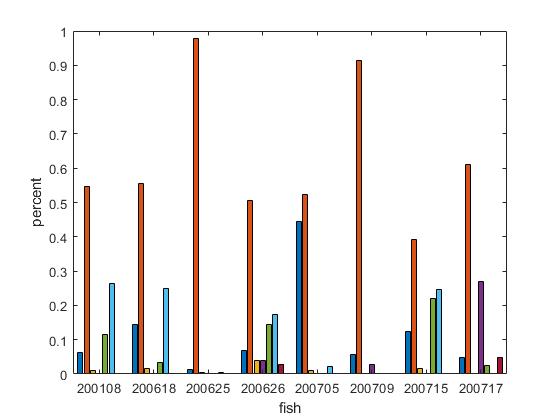

C = zeros(7,length(fishID));
for ifish = 1:length(fishID)
   idxtmp = (sum(numBout_per_fish(1:ifish-1))+1):sum(numBout_per_fish(1:ifish));
   C(:,ifish) = arrayfun(@(i) nnz(idx_apcluster(idxtmp)==i),1:7);
end
C = C./sum(C,1);
figure,
bar(C');
xlabel('fish');ylabel('percent');
set(gca,'XTickLabel',sessionID);

legend(arrayfun(@(i) ['cluster' num2str(i)],1:7,'un',0));

plot exemplars

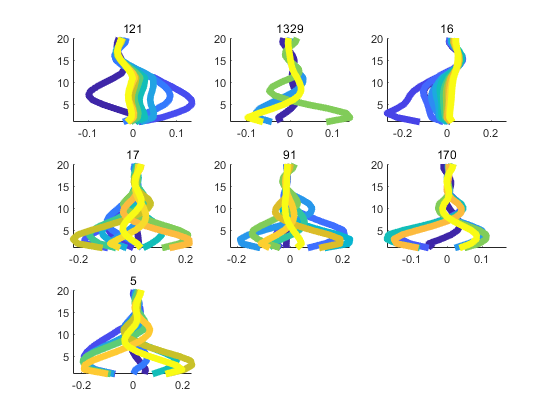

figure,
for i=1:7
    subplot(3,3,i)
    plot_continuous_bouts(gca,bout_single_curv{exemplar(i)});
    title(num2str(sz_cluster(i)));
end

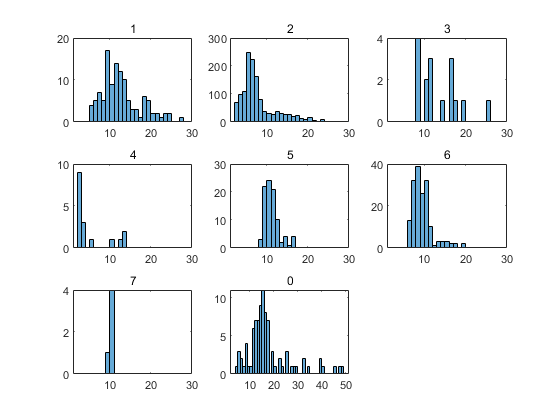

figure,
for i=1:7
    subplot(3,3,i),
    histogram(single_bout_len(idx_apcluster==i),'BinWidth',1);
    title(num2str(i));
    set(gca,'XLim',[1 30]);
end
subplot(3,3,8)
histogram(single_bout_len(idx_apcluster==0),'BinWidth',1);
title(num2str(0));